# Convolution and Filtering

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build some familiarity with MATLAB as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and they will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

**Suggested Prework**

The script [ConvolutionLTI.mlx](matlab:open('ConvolutionLTI.mlx')) explores the relationship between the convolution operation and linear time-invariant systems.

## Time and Frequency

In [ConvolutionLTI.mlx](matlab:open('ConvolutionLTI.mlx')), we show that convolving a signal with a rectangular pulse is equivalent to applying a moving average operation to the signal. Observe what happens in the frequency domain when a combination of sinusoids is convolved with a rectangular pulse signal.

  **Task.** Replace the empty signal in the text box below to compute linear convolution of $h(n)$ with $x(n)$ using [`conv`](https://www.mathworks.com/help/matlab/ref/conv.html) function setting the shape option to `"same"`**.**

% Time domain -> convolution
fs = 10000;                         % Sampling frequency
n = -10:1/fs:10;                    % Discretized time 

x = sin(n) + sin(10*n) + cos(5*n);  % Input signal is a combination of sinusoids at different frequencies
h = rectpuls(n);           % Impulse response of an LTI system/operation 
y = nan(size(x))./fs;       % Convolution of h(n) and x(n)

  **Task.** Replace the empty signal in the text box below to compute an element-wise product of $H(f)$ and $X(f)$. See [`.*`](https://www.mathworks.com/help/matlab/ref/times.html)

% Frequency domain -> multiplication
L = 2^nextpow2(length(n));   % Make length of fft to be the nearest next power of 2 for computation efficiency
f = 0:fs/L:fs-(fs/L);        % Discretized frequencies

X = abs(fft(x,L)./fs);       % Magnitude of FFT of x 
H = abs(fft(h,L)./fs);       % Magnitude of FFT of the impulse response h
Y = nan(size(X));    % Convolution theorem 

PlotSignals(n,h,x,y,f,H,X,Y);

  **Try**

- Use the drop-down to change `h` to different functions and observe the results in the time and frequency domains.

***Reflect***

In this example, you can think of $h(n)$ as an impulse response of a *filter*. Simply stated, filtering means removing undesirable components/features. The moving average operation can be thought of as "applying a filter" whose impulse response is a rectangular pulse. This removes higher frequency components.

**Weighted averaging **$\iff$ **Low-pass filtering**

*Considering* $x(n)$* as an input signal being filtered and *$y(n)$* as the output of the operation-*

- *What do you observe in the frequency domain when* $h(n)$* is a rectangular pulse? What does that imply about the moving average operation?*

- *What would be an ideal frequency response for *$h(n)$* (the blue dashed line) if we wish to retain only the low-frequency components in the output? (less than 0.5? less than 1?)*

- *Which of the signal options in the drop-down produce closest to ideal results?*

- *What may be the practical implications of trying to achieve an ideal frequency response for discrete-time systems?*

## Convolution in 2-D - Spatial Filtering

There are two ways to think about designing, implementing, or analyzing filters:

- Convolution by a time-domain filter (the desired impulse response)

- Multiplication by a frequency-domain filter (the desired frequency response)

In this script, we focus on the first way of implementing filters. This is widely used for processing digital images and digital audio. Since images are two-dimensional (2-D) discrete signals, let us first define a discrete 2-D convolution, which is simply an extension of the 1-D summation to 2-D.


$$w\left(i,j\right)=\sum_{m=-\infty }^{\infty } \sum_{n=-\infty }^{\infty } u\left(i,j\right)\cdot v\left(i-m,j-n\right)$$


 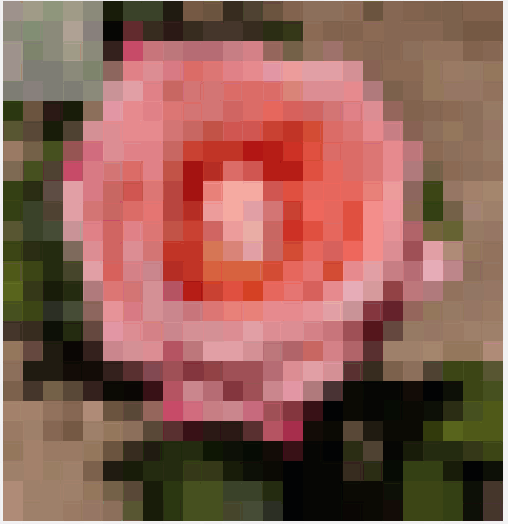

For images, the two dimensions are spatial (of space) instead of temporal (of time) typically encountered in 1-D signals. So, for 2-D signals such as images

**Weighted averaging **$\iff$** Spatial blurring **$\iff$** Low-pass filtering**

In this section, we will use 2-D convolution to blur this flower image by convolving it with a 2-D averaging filter.

Read an image using [`imread`](https://www.mathworks.com/help/matlab/ref/imread.html)`,` and display it using [`imshow`](https://www.mathworks.com/help/images/ref/imshow.html).

% Read image, visualize, and display its size and class.
I = imread("flower.jpg");

% Convert to double precision
I = im2double(I);

% Display
figure 
imshow(I)
whos I

  **Pro-tip**. In MATLAB, `double` matrices representing images are expected to have values in the range [0,1].

A color image like this one is a combination of three 2-D signals - one for red intensities, one for green, and one for blue. So, we will perform three separate 2-D convolutions to blur each of the three color planes (or intensity matrices).

% Split the image into the 3 component color intensity planes or matrices.
[R, G, B] = imsplit(I);
whos R                      

`R`, `G`, and `B` are now 2-D signals. Let's create a 2-D filter to blur them.

% Create a 2-D convolution filter or kernel for averaging or smoothing
W = 5;
h = ones(W)./W.^2

  **Task.** Use [`conv2`](https://www.mathworks.com/help/matlab/ref/conv2.html) to perform the three 2-D convolution operations in the text boxes provided. One of them has been pre-filled; complete the other two similarly. Use the `"same"` shape to ensure that the resulting image is the same size as the input. 

% Convolve R with h to blur the image
Ravg = conv2(R,h,"same");          

% Convolve G with h to blur the image
Gavg = nan(size(R));

% Convolve B with h to blur the image
Bavg = nan(size(R));

% Concatenate the three matrices to put together the color image
Iavg = cat(3,Ravg,Gavg,Bavg);        
whos Iavg
imshow(Iavg,[])

The function [`imfilter`](https://www.mathworks.com/help/images/ref/imfilter.html) makes the process of filtering images a lot easier. You can achieve the same result as we did in the task above by using `imfilter`.

Ifilt = imfilter(I,h,"conv");
whos Ifilt
imshow(Ifilt,[]);

This function is part of the Image Processing Toolbox™.

  **Try**

- Increase the filter size `W` by using the slider provided.

***Reflect***

- *What are the high-frequency components of an image? How does convolution with the averaging filter affect these?*

- *What is the effect of increasing the size of the filter?*

- *Look closely at the boundaries of the output image. What happens to the border pixels? Why?*

## More Spatial Filters

The values in the filter kernel or mask (`h`) determine the spatial components/features of the image to preserve. The filter kernel can contain any values. However, there are some kernels or masks, which are used often. Let's generate some commonly used masks and observe their effect on the image.

**Task.** Use the drop-down to switch between the filter kernels provided below.

% Read image from file
I = imread("flower.jpg");

% Define 3 different filter kernels
h1 = [1 2 1; 
      0 0 0; 
     -1 -2 -1]; %#ok<*NASGU> 

h2 = [1 0 -1; 
      2 0 -2; 
      1 0 -1];

h3 = [0 -1 0; 
     -1 5 -1; 
     0 -1 0];

h4 = [-1 -1 -1; 
      -1  9 -1;
      -1 -1 -1];

% Apply filters
Ifilt = imfilter(I,h3,"conv");

% Display the original image and the filtered image side-by-side
figure;
imshowpair(I,Ifilt,"montage");


  **Try**

- Go [here](https://www.mathworks.com/help/images/what-is-image-filtering-in-the-spatial-domain.html) to learn more about how convolution and correlation are closely related.

- Learn more about the different [options](https://www.mathworks.com/help/images/ref/imfilter.html#btsmcj2-1-options) available for `imfilter` and try using the input argument "`corr"`.

***Reflect***

- *What is your intuition about the effect of the different kernels on the image? Does it match up with the results that you get?*

## Practice Problem

Compute 2-D linear convolution, using [`fft2`](https://www.mathworks.com/help/matlab/ref/fft2.html)`,` to visualize the process of filtering in the frequency domain and to understand the notion of frequency in images. This is similar to computing convolution output via `fft` for 1-D signals.

Perform the tasks as directed to complete this code section.

% Import an image and display it.
figure;
I = imread("flower.jpg");

% For ease of analysis, convert the image to grayscale before further processing. 
I = im2gray(I);
imshow(I)

% Create some filter kernels to test. You can add your own to the list.
W = 15;
h1 = ones(W)./W.^2;

h2 = [1 0 -1; 
     2 0 -2; 
     1 0 -1];

h3 = [1 2 1; 
     0 0 0; 
    -1 -2 -1];

h4 = [-1 -1 -1; 
      -1  9 -1;
      -1 -1 -1];

h = h2

Compute the size for full linear convolution based on the size of the image and the filter kernel.

% Get the sizes of the image and filter kernel.
[MI, NI] = size(I);
[Mh, Nh] = size(h);

% Compute size of full convolution output for each dimension.
m        = MI+Mh+1;         % rows
n        = NI+Nh+1;         % columns

We use [`fft2`](https://www.mathworks.com/help/matlab/ref/fft2.html) to compute 2-D Fourier transform of image `I,` with a size of `m` rows and `n` columns. 

% Compute FFT of grayscale image.
F1 = fft2(I,m,n); 

We use [`imagesc`](https://www.mathworks.com/help/matlab/ref/imagesc.html) to visualize the 2-D FFT output with scaled colors to indicate the magnitude of FFT.

% Display FFT output using a colormap and log scale for better visualization.
imagesc(fftshift(log(1+abs(F1))))
colorbar

 **Task a. **Use [`fft2`](https://www.mathworks.com/help/matlab/ref/fft2.html) to compute 2-D Fourier transform of filter `h,` with a size of `m` rows and `n` columns. 

% Compute FFT of filter kernel.
F2 = nan(m,n);
% Display FFT output using a colormap and log scale for better visualization.
imagesc(fftshift(log(1+abs(F2))))
colorbar

 **Task b. **Multiply `F1` and `F2` element-wise.

% Convolution in spatial domain is multiplication in frequency domain.
F = nan(m,n);
% Display FFT output using a colormap and log scale for better
% visualization.
imagesc(fftshift(log(1+abs(F))))
colorbar

 **Task c.** Compute and inverse Fourier transform of the product `F` using [`ifft2`](https://www.mathworks.com/help/matlab/ref/ifft2.html). This will give us the filtered image. 

% Compute inverse FFT of the product.
Ifilt = nan(m,n);

Trim the image down to the right size to achieve the equivalent of linear convolution. Convert the image to unsigned 8-bit integer and view the output.

Ifilt = Ifilt(ceil(Mh/2):end-(ceil(Mh/2)+1), ceil(Nh/2):end-(ceil(Nh/2)+1));
Ifilt = uint8(real(Ifilt)); 
imshow(Ifilt)

 **Task d.** Perform the equivalent linear spatial convolution of `I` and `h` using [`imfilter`](https://www.mathworks.com/help/images/ref/imfilter.html) with the `"conv"` option. Verify if the results match.

Ifilt2 = nan(size(I));
imshow(Ifilt2)

 **Task e. **Try using different filter kernels from the drop-down at the top of this section and analyze the results.

## 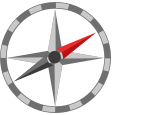**Further Exploration**

Spatial filtering of images is typically performed by applying the correlation operation. *Visit *[*the image filtering documentation page*](https://www.mathworks.com/help/images/what-is-image-filtering-in-the-spatial-domain.html)* to learn more about how convolution and correlation are closely related in the spatial domain. *

### Finding Patterns - Template Matching

In this example, we will count the number of times the letter "t" appears in this text.

     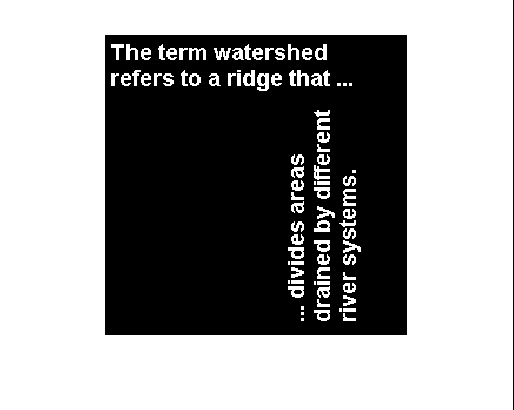      

  **Task a.** Analyze the code below and run this section to read and visualize the input images.

% Read an input image and a template image to match.
figure;
I = imread("text.png");
imshow(I)
title("Input text image")
template = imread("lettert.png");
imshow(template)
title("Template to match")

% Convert the image and the template to double-precision floating point to
% perform further computations.
I = im2double(I);
template = im2double(template);


  **Task b.** Replace the code in the text box to filter the image `I` with template `t.` Use the drop-down to choose the correlation option for `imfilter`.

result = imfilter(I, ones(3), "conv");

% Rescale image between 0 and 1, visualize the output.
result = rescale(result);
imshow(result)
title("Result of applying filtering operation")

% Locate the peak responses indicating a match and count the number of
% times it occurs.
t = 0.95;
imshow(result > t)
disp("Number of standing t's in the text = " + nnz(result > t))

  **Task c.** Manually verify whether the number of standing t's matches the true count.

### **C**onvolutional Neural Networks (CNNs)

The convolution operation is at the heart of deep learning networks used widely for finding patterns in images. The values contained in the convolution filter kernels/masks within these networks are often referred to as "weights". These networks typically contain layers and layers of convolution filters for the purpose of detecting and extracting useful patterns at various stages, depending on the problem at hand. The network learns these weights by going through (*training** on*) hundreds or thousands or even millions of images!

[Image source](https://www.mathworks.com/help/deeplearning/ug/deep-learning-in-matlab.html)

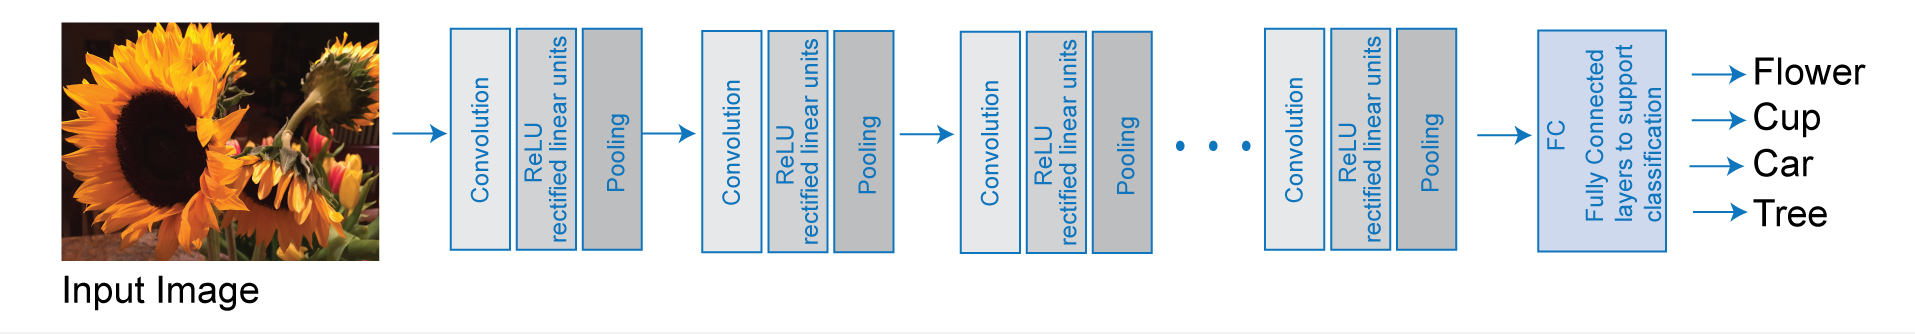

  **Pro-tip.** This demonstration requires [Deep Learning Toolbox™ Model for AlexNet Network](https://www.mathworks.com/matlabcentral/fileexchange/59133-deep-learning-toolbox-model-for-alexnet-network) support package. You can attempt to run the code below to determine if you need to install the support package. The error message will give explicit instructions if the pretrained `alexnet` is not installed.

  **Task.** Uncomment the next line of code to load a convolutional neural network trained to classify images.

% net = alexnet;                     

After loading the network once, you can use the drop-down below to test the network on different images.

im = imread("llama.jpg");  % Load an image to classify
im = imresize(im,[227 227]);        % Resize the image for the network
imshow(im);                         % Display image

  **Task.** Uncomment the next two lines of code to apply the trained network `net` to classify the image `im.`

% label = classify(net,im);        
% title(label)                        

For a free hands-on introduction to practical deep learning methods, see [Deep Learning Onramp](https://www.mathworks.com/training-schedule/deep-learning-onramp.html/?s_tid=doc_to_dlonramp).

[3 things you need to know about a Convolutional Neural Network](https://www.mathworks.com/solutions/deep-learning/convolutional-neural-network.html)

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

## **Helper Functions**

Function to visualize convolution in time domain and corresponding signals in the frequency domain.

function PlotSignals(n,hn,xn,yn,f,hf,xf,yf)
% PLOTSIGNALS(N,HN,XN,YN,F,HF,XF,YF) plots input signal, output signal, and the impulse
% response of a moving average operation in both time and frequency
% domains.

% Initialize a figure and a tiled layout.
figure("Position",[0 0 1000 350],"Color",[0.9 0.9 0.9])
tiledlayout(1,2,"TileSpacing","compact");

% Plot the signals in time domain.
nexttile
plot(n,hn,"--","LineWidth",2,SeriesIndex=1);
hold on 
plot(n,xn,"LineWidth",1.5,SeriesIndex=2);
plot(n,yn,"LineWidth",1.8,SeriesIndex=3);
hold off
xlim([-3 3])
ylim([-3 3])
xlabel("Time")
ylabel("Amplitude")
title("Time domain")
legend("h(n)","x(n)","y(n)","Location","northwest")

% Plot the signals in frequency domain.
nexttile;
plot(f,hf,"--","LineWidth",2,SeriesIndex=1);
hold on 
plot(f,xf,"LineWidth",1.5,SeriesIndex=2);
plot(f,yf,"LineWidth",1.8,SeriesIndex=3)
hold off
xlim([0,4])
ylim([0,2])
xlabel("Frequency")
ylabel("Magnitude")
title("Frequency domain")
legend("H(f)","X(f)","Y(f)","Location","northeast")

end

Function to create a movie demonstrating the linear convolution/correlation operation in 2-D.

function sequence = AnimateConvolution2D(filename)  %#ok<*DEFNU> 
% ANIMATECONVOLUTION2D(FILENAME) imports the image from a supported file
% format FILENAME and applies a 2-D smoothing filter to it. The output is
% an animation of the smoothing operation being applied as a sliding window
% operation.

I = imread(filename);                   % Read image file
I = im2double(imresize(I,0.04));        % Resize and convert to double

% Create 2-D filter (mask/kernel)
hsize = 5;  
hhalf = floor(hsize/2);
h = ones([hsize hsize size(I,3)])./hsize^2;        % Make the mask with same number of image planes as input
h = rot90(h,2);                                    % Flip the mask horizontally and vertically => rotate by 90 degrees

% Initialize variables to use in the loop
k = 1;                     % Counter for frames in sequence
J = I;                     % Output
Z = zeros(size(I(:,:,1))); % Mask full size
sequence = uint8([]);         % Create an empty sequence

% Compute the output of convolution pixel-by-pixel 
for m = hhalf+1:size(I,1)-hhalf       %row
    for n = hhalf+1:size(I,2)-hhalf   %col
      
       % Compute sum of product for location m,n 
       J(m,n,:) = sum(I(m-hhalf:m+hhalf,n-hhalf:n+hhalf,:).*h, [1,2]);
       
       % Indicate location of mask on a black image Z
       Z(m-hhalf:m+hhalf,n-hhalf:n+hhalf) =  1;
       
       % Overlay the mask position over the current iteration of convolution output
       Imask = labeloverlay(J,Z,"Colormap",[0.8 0.8 0.8]);
       sequence(:,:,:,k) = imresize(Imask,10,"Method","nearest");  % Resize using nearest method to get a zoomed-in appearance
       
       % Update variables for the next iteration
       Z = zeros(size(I(:,:,1)));
       k = k+1;
    end
end

end